%
% Basic plotting functions usage in YART
%  most of functions are built to handle fast animations
%
% - Make figure and change title
% - Plot coordinates
% - Plot box
% - Plot capsule
% - Plot interactive markers
% - Plot multiple sliders and text boxes
%
ccc

## Make figure and change title

ccc
for tick = 1:100 % loop
    fig_idx = 1;
    fig = set_fig(figure(fig_idx),'pos',[0.5,0.5,0.3,0.45],...
        'view_info',[80,26],'axis_info',[-1,+1,-1,+1,-1,+1],'AXIS_EQUAL',1,'GRID_ON',1,...
        'REMOVE_MENUBAR',1,'USE_DRAGZOOM',1,...
        'SET_CAMLIGHT',1,'SET_MATERIAL','METAL','SET_AXISLABEL',1,'afs',18);
    % Plot title
    title_str = sprintf('[%d] Figure $f(x) = \\exp(x)$',tick);
    plot_title(title_str,'fig_idx',fig_idx,...
        'tfs',35,'tfc','k','interpreter','latex');
    drawnow; 
    if ~ishandle(fig), break; end
end % for tick = 1:100 % loop


## Plot coordinates

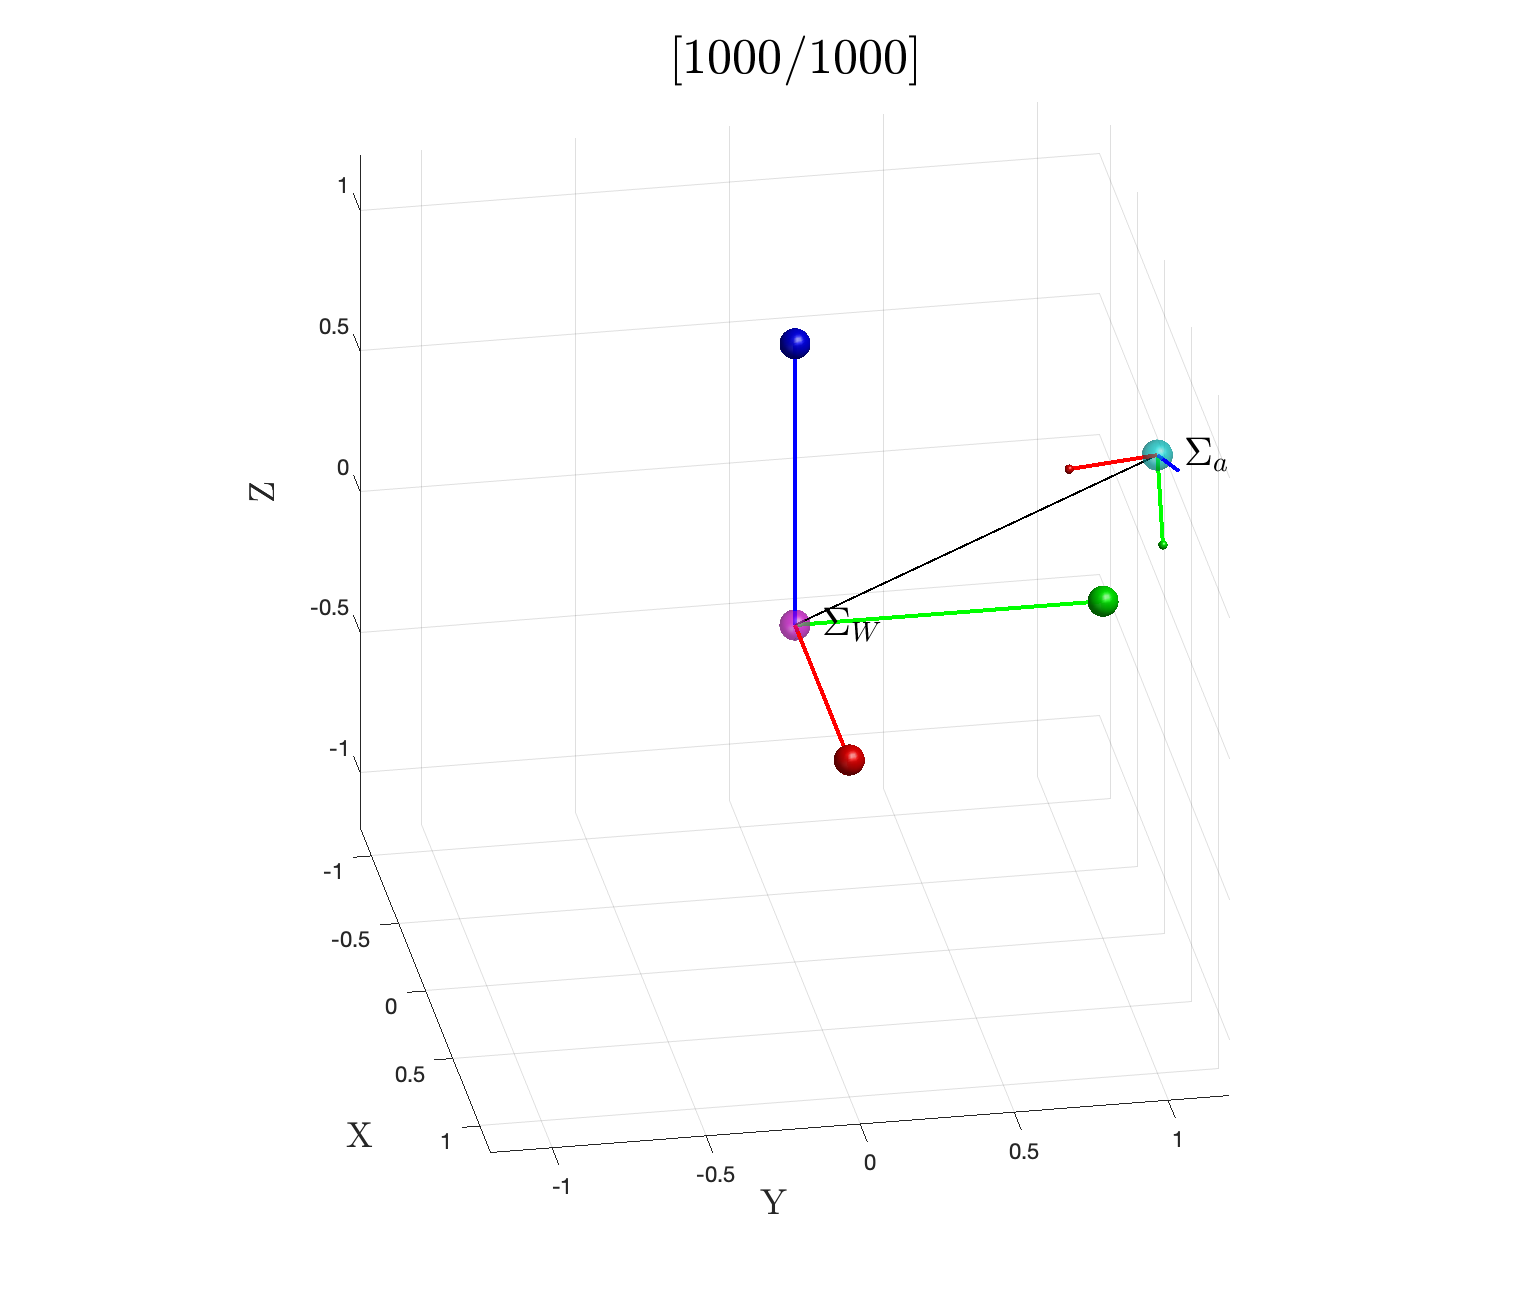

ccc
T_world = pr2t(cv([0,0,0]),rpy2r([0,0,0])); % world coordinate
max_tick = 1000;
for tick = 1:max_tick % loop
    % Run
    % tick이 늘면서 rotation 진행
    T_rot = pr2t(...
        cv(tick*0.001*[1,1,1]),...
        rpy2r(tick*D2R*cv([1,0,1]))...
        );
    T_local = T_rot*T_world;
    % Animate
    if mod(tick,5) == 0 % plot every 5 tick
        fig = set_fig(figure(1),'pos',[0.5,0.5,0.3,0.45],...
            'view_info',[80,26],'axis_info',1.2*[-1,+1,-1,+1,-1,+1],'AXIS_EQUAL',1,'GRID_ON',1,...
            'REMOVE_MENUBAR',1,'USE_DRAGZOOM',1,...
            'SET_CAMLIGHT',1,'SET_MATERIAL','METAL','SET_AXISLABEL',1,'afs',18);
        % Plot world coordinate
        plot_T(T_world,'fig_idx',1,'subfig_idx',1,...
            'PLOT_AXIS',1,'all',1.0,'alc','','alw',2,'als','-',...
            'PLOT_AXIS_TIP',1,'atr',0.05,...
            'PLOT_SPHERE',1,'sr',0.05,'sfc','m','sfa',0.5,...
            'text_str','$~~\Sigma_W$','text_fs',20,'text_color','k','text_interp','latex',...
            'USE_ZOOMRATE',1);
        % Plot local coordinate
        plot_T(T_local,'fig_idx',1,'subfig_idx',2,...
            'PLOT_AXIS',1,'all',0.3,'alc','','alw',2,'als','-',...
            'PLOT_AXIS_TIP',1,'atr',0.05,...
            'PLOT_SPHERE',1,'sr',0.05,'sfc','c','sfa',0.5,...
            'text_str','$~~\Sigma_a$','text_fs',20,'text_color','k','text_interp','latex',...
            'USE_ZOOMRATE',1);
        % Plot a line from world coordinate to local coordinate
        p_world = t2p(T_world);
        p_local = t2p(T_local);
        plot_line(p_world,p_local,'fig_idx',1,'lc','k','lw',1);
        % Plot title
        title_str = sprintf('[%d/%d]',tick,max_tick);
        plot_title(title_str,'fig_idx',1,'tfs',25,'tfc','k','interpreter','latex');
        drawnow;
        if ~ishandle(fig), break; end
    end
end % for tick = 1:100 % loop

## Plot a rotating box with keyboard control

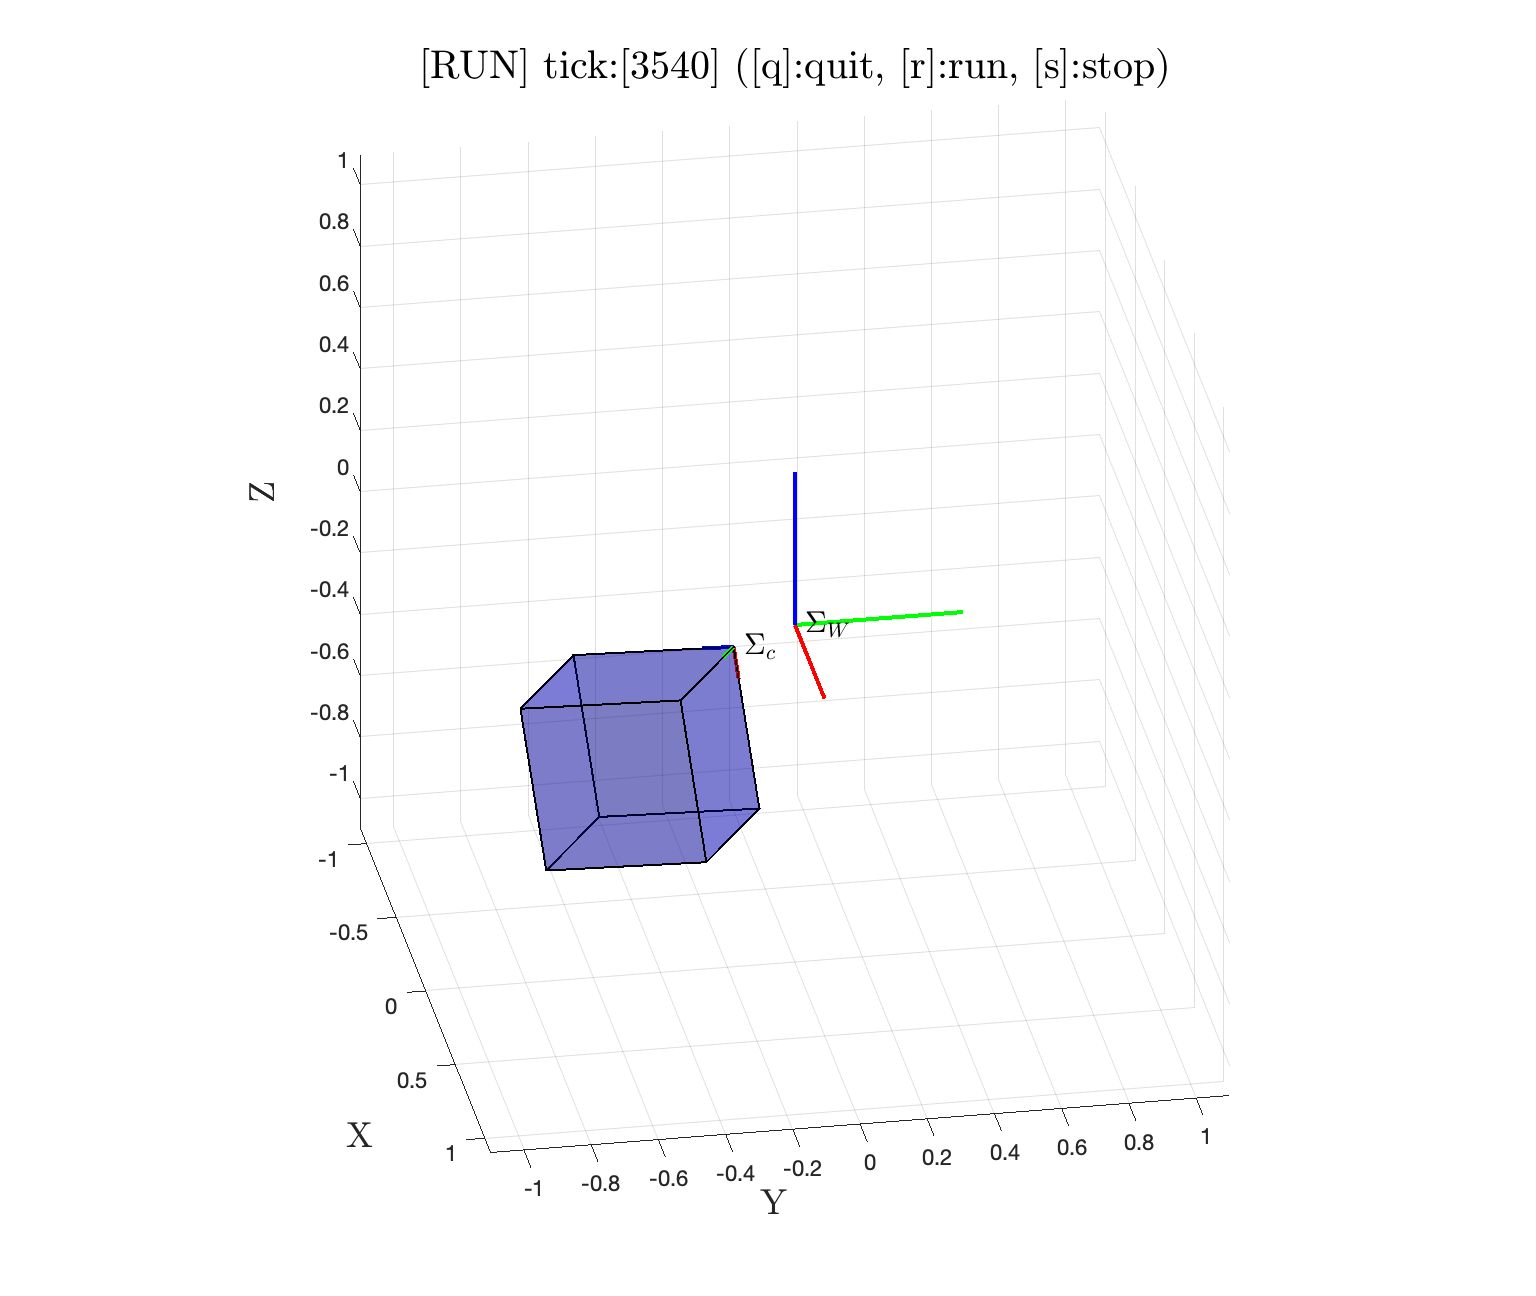

ccc
T_init = pr2t(0.2*randn(3,1),rpy2r(360*D2R*rand(3,1)));
T_cube = T_init;
run_mode = 'RUN'; tfc = 'k'; tick = 0;
while true
    % Update
    switch run_mode
        case 'RUN'
            tick = tick + 1;
            T_rot = pr2t('',rpy2r(tick*D2R*[0,0,1])); % z-axis rotate
            T_cube = T_rot * T_init;
    end
    % Animate
    if mod(tick,10) == 0
        fig = set_fig(figure(1),'pos',[0.5,0.5,0.3,0.45],...
            'view_info',[80,26],'axis_info',1.1*[-1,+1,-1,+1,-1,+1],'AXIS_EQUAL',1,'GRID_ON',1,...
            'REMOVE_MENUBAR',1,'USE_DRAGZOOM',1,'SET_CAMLIGHT',1,'SET_MATERIAL','METAL',...
            'SET_AXISLABEL',1,'afs',18,'interpreter','latex');
        % Plot world coordinate
        plot_T(pr2t('',''),'fig_idx',1,'subfig_idx',1,...
            'all',0.5,'text_str','~$\Sigma_W$','text_interp','latex','USE_ZOOMRATE',1);
        % Plot cube coordinate
        plot_T(T_cube,'fig_idx',1,'subfig_idx',2,...
            'all',0.1,'text_str','~$\Sigma_c$','text_interp','latex','USE_ZOOMRATE',1);
        % Plot cube
        xyz_min = cv([0,0,0]);
        xyz_len = cv([0.5,0.5,0.5]);
        plot_cube(T_cube,xyz_min,xyz_len,'fig_idx',1,'subfig_idx',1,...
            'bfc','b','bfa',0.3,'bec','k');
        % Plot title
        title_str = sprintf('[%s] tick:[%d] ([q]:quit, [r]:run, [s]:stop)',...
            run_mode,tick);
        plot_title(title_str,'tfs',20,'tfc',tfc,'interpreter','latex');
        drawnow;
        if ~ishandle(fig), break; end
    end
    
    % Keyboard control using global variable
    if ~isempty(g_key)
        switch g_key
            case 'q'
                break
            case 'r'
                run_mode = 'RUN'; tfc = 'b';
            case 's'
                run_mode = 'STOP'; tfc = 'k';
        end
        g_key = '';
    end
end

if ishandle(fig)
    plot_title('Terminated','tfs',20,'tfc','r','interpreter','latex');
end

## Plot capsule

ccc

% Define capsule coordinates {T_cap}
p_cap = cv(1.0*rand(1,3));
R_cap = rpy2r(20*randn(1,3)*D2R);
T_cap_init = pr2t(p_cap,R_cap);
T_cap = T_cap_init;

% Define capusle offset coordinates w.r.t. {T_cap}
p_offset = cv(0.2*rand(1,3));
R_offset = rpy2r(20*randn(1,3)*D2R);
T_offset = pr2t(p_offset,R_offset);
cap = get_capsule_shape('T_offset',T_offset,'radius',0.2,'height',0.5);

% Capsule center coordinates
T_cap_center = T_cap_init*T_offset;

% Get capsule line
cl = get_capsule_line(T_cap_init,cap);

% loop
tick = 0; run_mode = 'STOP'; tfc = 'k';
while true
    % Run 
    switch run_mode
        case 'RUN'
            tick = tick + 1;
            T_rot = pr2t('',rpy2r(tick*D2R*[0,0,1])); % rotate z-axis w.r.t. {T_cap}
            T_cap = T_cap_init * T_rot; % rotate globally 
            T_cap_center = T_cap*T_offset; % capsule center pose
            cl = get_capsule_line(T_cap,cap); % capsule line 
        otherwise
            pause(1e-6);
    end
    
    % Animate
    if mod(tick,10) == 0
        % Plot the capsule in {W} coordinatesㅂㅂ
        fig = set_fig(figure(1),...
            'pos',[0.0,0.5,0.3,0.5],'view_info',[88,16],...
            'axis_info',1.5*[-1/10,+1,-1/10,+1,-1/10,+1],...
            'AXIS_EQUAL',1,'GRID_ON',1,'REMOVE_MENUBAR',1,'USE_DRAGZOOM',1,...
            'SET_CAMLIGHT',1,'SET_MATERIAL','METAL','SET_AXISLABEL',1,'afs',20);
        plot_T(pr2t('',''),'fig_idx',1,'subfig_idx',1,...
            'PLOT_AXIS',1,'all',1.0,'alc','','text_str','$\Sigma_W$','text_fs',30,'text_interp','latex');
        plot_T(T_cap,'fig_idx',1,'subfig_idx',2,...
            'PLOT_AXIS',1,'all',0.2,'PLOT_AXIS_TIP',1,...
            'text_str','~Capsule Pose','text_fs',20,'text_interp','latex');
        plot_T(T_cap_center,'fig_idx',1,'subfig_idx',3,...
            'PLOT_AXIS',1,'all',0.1,'alw',3,'PLOT_AXIS_TIP',1,...
            'text_str','~Capsule Center','text_fs',20,'text_interp','latex');
        plot_capsule(cap,'fig_idx',1,'T',T_cap,'cfc','y','cfa',0.3,'cec','none','cea',0.2);
        plot_line(cv([0,0,0]),t2p(T_cap),'fig_idx',1,'subfig_idx',1,...
            'lc',0.3*[1,1,1],'lw',1,'ls','-','USE_ZOOMRATE',1);
        plot_line(t2p(T_cap),t2p(T_cap_center),'fig_idx',1,'subfig_idx',2,...
            'lc',0.3*[1,1,1],'lw',1,'ls','-','USE_ZOOMRATE',1);
        plot_line(cl.p1,cl.p2,'fig_idx',1,'subfig_idx',3,...
            'lc',0.3*[1,1,1],'lw',1,'ls','-','PLOT_LINE_TIP',1,'ltfc','r','ltfa',0.9,'ltr',0.02,...
            'USE_ZOOMRATE',1);
        title_str = sprintf('[%s][%d] Capusule ([r]:run [s]:stop [q]:quit)',run_mode,tick);
        plot_title(title_str,'fig_idx',1,'tfc',tfc,'tfs',20,'interpreter','latex');
        drawnow; if ~ishandle(fig), break; end
    end
    % Keyboard handler
    if ~isempty(g_key) % if key pressed
        switch g_key
            case 'q'       % press 'q' to quit
                break;
            case 's'       % press 's' to stop
                run_mode = 'STOP';
                tfc      = 'k';
            case 'r'       % press 'r' to run
                run_mode = 'RUN';
                tfc      = 'b';
        end
        g_key = ''; % reset key pressed
    end % if ~isempty(g_key) % if key pressed
end
if ishandle(fig), plot_title('Terminated','fig_idx',1,'tfs',20,'tfc','r'); end
fprintf('Done.\n');

## Plot interactive markers

ccc
% Plot interactive markers
fig = set_fig(figure(1),'pos',[0.0,0.5,0.5,0.5],...
    'view_info',[88,16],'axis_info',5*[-1,+1,-2,+2,-1,+1],'AXIS_EQUAL',1,'GRID_ON',1,...
    'REMOVE_MENUBAR',1,'USE_DRAGZOOM',1,'SET_CAMLIGHT',1,'SET_MATERIAL','METAL',...
    'SET_AXISLABEL',1,'afs',18,'interpreter','latex');
plot_interactive_marker('subfig_idx',1,'T',pr2t([0,0,-2],rpy2r(zeros(1,3))),'clen',2.0);
plot_interactive_marker('subfig_idx',2,'T',pr2t([0,0,+2],rpy2r(zeros(1,3))),'clen',2.0);
tick = 0;
while ishandle(fig)
    tick = tick + 1;
    title_str = sprintf('[%d] p1:%s rpy1:%s \np2:%s rpy2:%s',...
        tick,...
        vec2str(t2p(g_im{1}.T)','%.1f'),...
        vec2str(R2D*r2rpy(t2r(g_im{1}.T)),'%.0f'),...
        vec2str(t2p(g_im{2}.T)','%.1f'),...
        vec2str(R2D*r2rpy(t2r(g_im{2}.T)),'%.0f'));
    plot_title(title_str,'interpreter','latex','tfs',18);
    drawnow;
end